# Taller II

### 02/04/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 1 y 2*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- No olvidar el criterio de parada de ErrorRelativo, ya que en general este error converge primero que el Error Absoluto, y esto detiene el metodo antes de un delta deseado, si el método se encuentra programado de esta manera es importante no modificar este criterio, y de igual manera esto se verá reflejado en el criterio $\textrm{Err}$ que nos retorna el método.

- Importante, pero esto es más un recordatorio. Matlab es además de un software un lenguaje, así podemos tareas repetitivas volverlas métodos iterativos, eso es lo que se les propone con el método **Jac_GS**, invitarlos a que exploren la posibilidad y realicen métodos que les haga la vida más fácil.

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Métodos de una variable*

`    [c, err, n] = bisect(Function, Num1, Num2, Tol), `Método de bisección.

            - Function funcion definida @

            - Num1 y Num2 son los extremos del intervalo

            - Tol Es la tolerancia definida a la iteración

            - c es la aproximación obtenida por el método

            - err Error asociado a la iteración

            - n Pasos realizados para alcanzar la tolerancia

`    [p, k, err, P] = fixpt(g, p0, tol, max1), `Método de punto fijo.

            - g funcion creada con @

            - p0 es el supuesto inicial para el punto fijo

            - tol es la tolerancia

            - max1 es el numero maximo de iteraciones

            - p es la aproximacion del punto fijo

            - k es el numero de iteraciones realizadas

            - err es el error en la aproximacion

            - P' contiene la secuencia {pn}

`    [p, err, k, yc] = newton(f, df, p0, delta, epsilon, max1), `Método de Newton.

            - f funcion creada con @

            - df funcion derivada creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

`    [p, err, k, yc] = newton(f, df, d2f, p0, delta, epsilon, max1), `Método de Newton modificado.

            - f funcion creada con @

            - df primera derivada, funcion creada con @

            - d2f segunda derivada, funcion creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

*Frente a la definición del método de Newton acelerado, recordemos que este puede ser invocado usando el método de Newton y agrendando la multiplicidad de la raiz a hallar en la definición de la función o en la definición de la derivada de la función, tal como se indica:*

$x_{k+1} =x_k -M\frac{\;f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$ : Definimos entonces $f\left(x_k \right):=M\;f\left(x\right)\;|\;f^{\prime } \left(x_k \right):=\frac{f^{\prime } \left(x\right)}{M}$.

#### *        Métodos de sistemas de ecuaciones*

`    X = jacobi(A, B, P, delta, max1), `Método de Jacobi.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; los supuestos iniciales

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de jacobi a

                la solucion de  AX = B

`    X = gseid(A, B, P, delta, max1), `Método de Gauss - Seidel.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de gauss-seidel a

                la solucion de  AX = B

`    Y = sor(A, B, P, w, delta, max1), `Método de SOR

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - w parametro de sobrerelajacion (0<w<2)

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

             - Y es una matriz  N x 1: la aproximacion de SOR a

                la solucion de  AX = B

`    P = newdim (F, JF, P, delta, epsilon, max1), `Método de Newton

            - F funcion del sistema creada con @

            - JF matriz jacobiana, funcion creada con @

            - P es la aproximacion inicial a la solucion

            - delta es la tolerancia para  P

            - epsilon es la tolerancia para  F(P)

            - max1 es el numero maximo de iteraciones

            - P es la aproximacion a la solucion

            - iter es el numero de iteraciones realizadas

            - err es el error estimado para  P

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

#### Matrices

Se resuelven los ejercicios $\left.\left.\left.1\ldotp b\right),2\ldotp b\right),8\ldotp b\right),11$, se propone el uso de Jacobi, SOR y manipulación propiad de Matlab

**1.** Calcule $||x||_{\infty } ,||x||_1 ,||x||_2 ,$ para cada uno de los siguientes vectores.

**    b) **$x={\left\lbrack -2,3,4,-3,-1,2\right\rbrack }^T$

clear

x = [-2 3 4 -3 -1 2]';
norm(x, 'inf'), norm(x, 1), norm(x), norm(x, 2) % Normas del vector

ans = 4

ans = 15

ans = 6.5574

ans = 6.5574

**2.** Demuestre que las siguientes sucesiones son convergentes y encuentre sus límites:

**    b) **$x^{\left(k\right)} =\left\lbrack \frac{3\;k+1}{k^2 },\left(\frac{1}{k}\right)\ln \left(k\right),k^2 \;e^{-k} ,\;\frac{2\;k}{1+2k}\right\rbrack$

Veamos que para demostrar que la sucesión dada por el vector, es necesario demostrar el valor limite al que converge esta sucesión, así definimos el limite a infinito del vector:

clear
syms x(k)

x(k) = [(3*k +1)/k^2, log(k) /k, k^2 * exp(-k), 2*k / (1 + 2*k)]

$$x(k) = \left(\begin{array}{cccc} \frac{3\,k+1}{k^{2}} & \frac{\log\left(k\right)}{k} & k^{2}\,{\mathrm{e}}^{-k} & \frac{2\,k}{2\,k+1} \end{array}\right)$$

limit(x, inf)

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 1 \end{array}\right)$$

**8.** En cada caso, utilice los métodos de Jacobi y Gauss-Seidel para aproximar las soluciones de los sistemas lineales Ax = b. En todos los casos use el vector nulo como primera aproximación.

**    b) **$A=\left\lbrack \begin{array}{cccc}
4 & 1 & -1 & 1\\
1 & 4 & -1 & -1\\
-1 & -1 & 5 & 1\\
1 & -1 & 1 & 3
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
-2\\
-1\\
0\\
1
\end{array}\right\rbrack$

clear

A = [4 1 -1 1; 1 4 -1 -1; -1 -1 5 1; 1 -1 1 3]

A =      4     1    -1     1
     1     4    -1    -1
    -1    -1     5     1
     1    -1     1     3


b = [-2 -1 0 1]'

b =     -2
    -1
     0
     1


x0 = zeros(size(b))

x0 =      0
     0
     0
     0


XJ = jacobi(A, b, x0, 1e-15, 300)

k = 68

err = 1.0296e-15

relerr = 9.6994e-16

XJ =    -0.7534
    0.0411
   -0.2808
    0.6918


XG = gseid(A, b, x0, 1-15, 400)

k = 400

err = 0

relerr = 0

XG =    -0.7534
    0.0411
   -0.2808
    0.6918


norm(XJ - XG)

ans = 1.2677e-15

help Jac_GS

  Entrada  - A es una matriz no singular  N x N
 	       - w es el omega, parametro relajación SOR
             (Este parametro es opcional)
  Salida   - TJ es una matriz  n x n, asociada al método de iteracion
             de Jacobi
           - TGS es una matriz  n x n, asociada al método de iteracion
             de Gauss - Seidel
           - Tw es una matriz  n x n, asociada al método de iteracion
             de SOR(Succesive Over Relaxation)



Jac_GS(A)

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.6054

ratioTGS = 0.3553

ratioTw = 0.3553

ans =          0   -0.2500    0.2500   -0.2500
   -0.2500         0    0.2500    0.2500
    0.2000    0.2000         0   -0.2000
   -0.3333    0.3333   -0.3333         0


**11.** Sean $A=\left\lbrack \begin{array}{ccc}
1 & 0 & -1\\
-\frac{1}{2} & 1 & -\frac{1}{4}\\
1 & -\frac{1}{2} & 1
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
\frac{1}{5}\\
-1\ldotp 425\\
2
\end{array}\right\rbrack$

**    a. **Nos interesa resolver $\textrm{Ax}=b$ por los métodos de Jacobi y Gauss-Seidel. Demuestre que los dos métodos iterativos convergen.

**    b.** En lugar de $-1$ utilice $-2$ en la componente $\left(1,3\right)$ de $A$. ¿Siguen siendo convergentes los dos métodos?

clear

A = [1 0 -1; -1/2 1 -1/4; 1 -1/2 1];
b = [1/5 -1.425 2]';
x0 = zeros(size(b));

help diag

 diag Diagonal matrices and diagonals of a matrix.
    diag(V,K) when V is a vector with N components is a square matrix
    of order N+ABS(K) with the elements of V on the K-th diagonal. K = 0
    is the main diagonal, K > 0 is above the main diagonal and K < 0
    is below the main diagonal. 
 
    diag(V) is the same as diag(V,0) and puts V on the main diagonal.
 
    diag(X,K) when X is a matrix is a column vector formed from
    the elements of the K-th diagonal of X.
 
    diag(X) is the main diagonal of X. diag(diag(X)) is a diagonal matrix.
 
    Example
       m = 5;
       diag(-m:m) + diag(ones(2*m,1),1) + diag(ones(2*m,1),-1)
    produces a tridiagonal matrix of order 2*m+1.
 
    See also spdiags, triu, t

D = diag(diag(A))

D =      1     0     0
     0     1     0
     0     0     1


L = - tril(A, -1)

L =          0         0         0
    0.5000         0         0
   -1.0000    0.5000         0


U = - triu(A, 1)

U =          0         0    1.0000
         0         0    0.2500
         0         0         0



$$D^{-1} \;A\;\not= A\;D^{-1}$$


TJ = D \ (L + U)

TJ =          0         0    1.0000
    0.5000         0    0.2500
   -1.0000    0.5000         0


norm(eigs(TJ), 'inf')

ans = 0.9721

Jac_GS(A)

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.9721

ratioTGS = 0.6250

ratioTw = 0.6250

ans =          0         0    1.0000
    0.5000         0    0.2500
   -1.0000    0.5000         0


X = jacobi(A, b, x0, 1e-15, 1000)

k = 1000

err = 1.3089e-12

relerr = 9.3970e-13

X =     0.9000
   -0.8000
    0.7000


X = gseid(A, b, x0, 1e-15, 300)

k = 77

err = 9.1551e-16

relerr = 6.5730e-16

X =     0.9000
   -0.8000
    0.7000


A(1, 3) = -2;
A

A =     1.0000         0   -2.0000
   -0.5000    1.0000   -0.2500
    1.0000   -0.5000    1.0000


Jac_GS(A, 1/2)

Radio Espectral


ratioTJ = 1.3933

ratioTGS = 1.3750

ratioTw = 0.5751

ans =          0         0    2.0000
    0.5000         0    0.2500
   -1.0000    0.5000         0


X = gseid(A, b, x0, 1e-10, 500)

k = 500

err = 2.3274e+69

relerr = 1.7273

X = 	1.0e+68 *

    9.8711
    6.1694
   -6.7864


X = sor(A, b, x0, 1/2, 1e-15, 300)

k = 61

err = 1.0949e-15

relerr = 7.5594e-16

X =     1.1579
   -0.7263
    0.4789


#### Sistemas lineales y no lineales    

Se resuelven los ejercicios $\left.2\ldotp b\right),4$, se propone el uso de Jacobi, SOR y Newton Multivariado

**2.** En cada caso, utilice el método de SOR con  $\omega =1,1:0,1:1,6$ (notación MATLAB) para aproximar las soluciones de los sistemas lineales $A\;x=b$. En todos los casos use máximo número de iteraciones igual a $\textrm{maxIter}=3000$, tolerancia $\mathrm{delta}={10}^{-5}$ y el vector nulo como primera aproximación. Determine las normas de los vectores residual y error. Use la norma 2.

**    b) **$A=\textrm{gallery}\left(\prime {\textrm{dorr}}^{\prime } ,10\right)$ con $b=A*\mathrm{ones}\left(10,1\right)$ y $p=\textrm{zeros}\left(10,1\right)$

${\textrm{Residual}\;x}_r =A\;x^* -b$, $\mathrm{Error}\;=\;x-x^*$


$$A\;x=b\to A\;\mathrm{Ones}=b$$
 

clear
A = gallery('dorr', 10);
b = A * ones(10,1); % A x = b
c = A\b;
x0 = zeros(size(b));

X = sor(A, b, x0, 1.1, 1e-5, 3000);
% X = jacobi(A, b, x0, 1e-5, 3000);
Err = norm(c - X)

Err = 0.0096

Res = norm(A * X - b)

Res = 8.3063e-05

for w = 1.1:.1:1.6
    disp('Para el valor de Omega:') % Mostrar en pantalla
    w
    X = sor(A, b, x0, w, 1e-5, 3000);
    Err = norm(c - X)
    Res = norm(A * X - b)
end

Para el valor de Omega:


w = 1.1000

Err = 0.0096

Res = 8.3063e-05

Para el valor de Omega:


w = 1.2000

Err = 0.0079

Res = 7.4646e-05

Para el valor de Omega:


w = 1.3000

Err = 0.0063

Res = 6.8028e-05

Para el valor de Omega:


w = 1.4000

Err = 0.0050

Res = 6.3163e-05

Para el valor de Omega:


w = 1.5000

Err = 0.0039

Res = 5.9652e-05

Para el valor de Omega:


w = 1.6000

Err = 0.0029

Res = 5.6990e-05

help table

 table Table.
    Tables are used to collect heterogeneous data and metadata into a single
    container.  Tables are suitable for storing column-oriented or tabular data
    that are often stored as columns in a text file or in a spreadsheet.  Tables
    can accommodate variables of different types, sizes, units, etc.  They are
    often used to store experimental data, with rows representing different
    observations and columns representing different measured variables.
 
    Use the table constructor to create a table from variables in the MATLAB
    workspace.  Use the readtable function to create a table by reading data
    from a text or spreadsheet file.
 
    The table constructor can also be used to create tables without
    providing workspace variables, by providing the size and variable
    types.
 
    Tables can be subscripted using parentheses much like ordinary numeric
    arrays, but in addition to numeric and logica

**4. **Sea


$$A=\left\lbrack \begin{array}{ccc}
1 & \alpha  & \alpha \\
\alpha  & 1 & \alpha \\
\alpha  & \alpha  & 1
\end{array}\right\rbrack$$


Demuestre que A es positiva definida cuando $\alpha \;\in I=\left(-\frac{1}{2},1\right)$ y es estrictamente diagonalmente dominante para $\alpha \;\in J=\left(-\frac{1}{2},\;\frac{1}{2}\right)$. En la siguiente tabla escriba C, NC, NS si el respectivo método Converge, No Converge o No Sabe si converge o no converge.

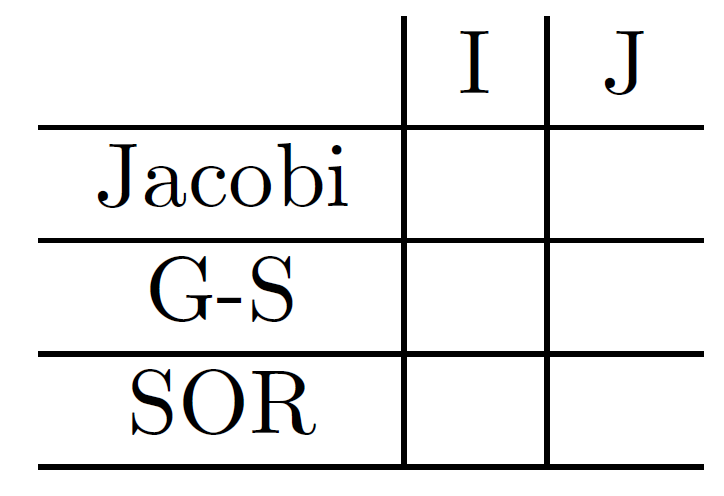

clear
syms alpha lambda

A = [1 alpha alpha; alpha 1 alpha; alpha alpha 1]

$$A = \left(\begin{array}{ccc} 1 & \alpha & \alpha \\ \alpha & 1 & \alpha \\ \alpha & \alpha & 1 \end{array}\right)$$

PC = charpoly(A);
PC = poly2sym(PC, lambda)

$$PC = 3\,\alpha^{2}-\lambda \,\left(3\,\alpha^{2}-3\right)-2\,\alpha^{3}-3\,\lambda^{2}+\lambda^{3}-1$$

solve(PC == 0, lambda)

$$ans = \left(\begin{array}{c} 1-\alpha \\ 1-\alpha \\ 2\,\alpha +1 \end{array}\right)$$

polyC = det(A - lambda * eye(size(A)))

$$polyC = 2\,\alpha^{3}+3\,\alpha^{2}\,\lambda -3\,\alpha^{2}-\lambda^{3}+3\,\lambda^{2}-3\,\lambda +1$$

solve(polyC == 0, lambda)

$$ans = \left(\begin{array}{c} 1-\alpha \\ 1-\alpha \\ 2\,\alpha +1 \end{array}\right)$$


$$\begin{array}{l}
1-\alpha >0\to \alpha <1\\
2\;\alpha +1>0\to \alpha >-\frac{1}{2}\\
\alpha \in \left(-\frac{1}{2},1\right)
\end{array}$$


disp(A)

$$\left(\begin{array}{ccc} 1 & \alpha & \alpha \\ \alpha & 1 & \alpha \\ \alpha & \alpha & 1 \end{array}\right)$$


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
1>2\;|\alpha |\;\\
1>2\;|\alpha |\;\\
1>2\;|\alpha |\;
\end{array}\right\rbrack \to 1>2\;|\alpha |\to -\frac{1}{2}<\alpha <\frac{1}{2}\\
\alpha \in \left(-\frac{1}{2},\frac{1}{2}\right)
\end{array}$$


En $I$ el método de SOR y Gauss - Seidel converge: Jacobi No se sabe

En $J$ el método de Jacobi y Gauss - Seidel converge.

Verificar la convergencia de Jacobi en el intervalo $I$:

I = [-1/2, 1];
% i = -.5:.2:1
for i = -.5:.2:1
    B = eval(subs(A, alpha, i)); % Sustituyo los valores para iterar
    disp('Para el valor de i =')
    disp(i)
    [~] = Jac_GS(B)
end

Para el valor de i =


   -0.5000



Radio Espectral


ratioTJ = 1.0000

Para el valor de i =


   -0.3000



Radio Espectral


ratioTJ = 0.6000

Para el valor de i =


   -0.1000



Radio Espectral


ratioTJ = 0.2000

Para el valor de i =


    0.1000



Radio Espectral


ratioTJ = 0.2000

Para el valor de i =


    0.3000



Radio Espectral


ratioTJ = 0.6000

Para el valor de i =


    0.5000



Radio Espectral


ratioTJ = 1.0000

Para el valor de i =


    0.7000



Radio Espectral


ratioTJ = 1.4000

Para el valor de i =


    0.9000



Radio Espectral


ratioTJ = 1.8000

clear

A = [1 0 -1; -1/2 1 -1/4; 1 -1/2 1];
b = [1/5 -1.425 2]';
x0 = zeros(size(b));
w = 1.2

w = 1.2000


D = diag(diag(A));
L = - tril(A, -1);
U = - triu(A, 1);

Tw = (D - w*L) \ ((1 - w) * D + w * U)

Tw =    -0.2000         0    1.2000
   -0.1200   -0.2000    1.0200
    0.1680   -0.1200   -1.0280


[~, ~, Tw] = Jac_GS(A, w)

Radio Espectral


ratioTJ = 0.9721

Tw =    -0.2000         0    1.2000
   -0.1200   -0.2000    1.0200
    0.1680   -0.1200   -1.0280
